% HW 1 УПравление дин системами Смолкина
warning off
clear
close all
pack
clc
format short

# Зададим Матрицы системы и параметры системы

% data
syms t tau

comment = 'Матрицы системы и параметры системы'

comment = 'Матрицы системы и параметры системы'


T = 2040

T = 2040

dt = 10

dt = 10

N = T/dt+1

N = 205

tc = 0:dt:T

tc =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300   310   320   330   340   350   360   370   380   390   400   410   420   430   440   450   460   470   480   490



n = 3

n = 3

m = 1

m = 1

A = [0                 -1.53921/41.1368    (-1.53921/41.1368)*0.62; ...
         41.1368*10.^(-6)   0                   0; ...
         0                  1.5*10.^(-3)        1.5*10.^(-3)]

A =          0   -0.0374   -0.0232
    0.0000         0         0
         0    0.0015    0.0015



X0 = [0.3; 0.01; 0.01]

X0 =     0.3000
    0.0100
    0.0100


 Нам также дано ограничение на управление:


$$|u\left(t\right)|\le 0,6401\cdot {10}^{-3}$$


В связи с этим выполним нормировку следующего вида:


$$\overset{\_}{u} \left(t\right)=\frac{1}{0,6401*{10}^{-3} }u\left(t\right)$$


тогда матрица В примет вид:

B = [1;0;0];
B = B*0.6401*10^-3

B = 	1.0e+-3 *

    0.6401
         0
         0


B

B = 	1.0e+-3 *

    0.6401
         0
         0


В нашей задаче мы хотим минимизировать функционал

$J\left(u\right)=\frac{1}{2}\int_0^{\infty } \left(u,u\right)\textrm{dt}\to \min$, который по сути означает минимизирование времени.

# **Проверим устойчивость разомкнутой системы**


$$\overset{\cdot }{X\;} =A\cdot X$$


Проверим устойчивость разомкнутой системы. Посмотрим на собственный чила.

Система* устойчива* если все вещественные числа < 0

cpmment ='собственный чила'

cpmment = 'собственный чила'

poles = eig(A)

poles = 	1.0e+-3 *

   0.3088 + 0.9481i
   0.3088 - 0.9481i
   0.8824 + 0.0000i



if poles < 0
    display('система устойчива');
else display('размокнутая система неустойчива');
end

размокнутая система неустойчива


display('Система без управления неустойчива')

Система без управления неустойчива


Тк Poles положительный, то система **размокнутая система неустойчива**

# Теперь проверим управляемость системы

states = {'x' 'x_dot' 'phy' 'phy_dot'}

states = 1×4 cell array
    {'x'}    {'x_dot'}    {'phy'}    {'phy_dot'}


inputs = {'u'}

inputs = 1×1 cell array
    {'u'}


outputs = {'x' 'phy'}

outputs = 1×2 cell array
    {'x'}    {'phy'}


*x' *= *Ax*+*Bu*

*y *= *Cx*+*Du, C=0 D = 0*

C = [0 0 0;
     0 0 0]

C =      0     0     0
     0     0     0


D = [0;
     0] %  учавствует в выходе у

D =      0
     0


display('Система пространства состояний')

Система пространства состояний


sys_ss = ss(A, B, C, D, 'inputname', inputs, 'outputname', outputs);
display(' наша система, у которой проверяем управляемость')

 наша система, у которой проверяем управляемость


display('Строим матрицу управляемости')

Строим матрицу управляемости


display('[B AB .. A^(n-1)B]')

[B AB .. A^(n-1)B]


cm = ctrb(sys_ss)

cm = 	1.0e+-3 *

    0.6401         0   -0.0000
         0    0.0000         0
         0         0    0.0000


cm 

cm = 	1.0e+-3 *

    0.6401         0   -0.0000
         0    0.0000         0
         0         0    0.0000


% проверяем полного ли она ранга
controllability = rank(cm)

controllability = 3


if controllability == 3
    display('Ситема управляема');
else display('Система неуправляема');
end

Ситема управляема



% самостоятельно построим матрицу управляемости
G = [B A*B A^2*B];
if rank(G) ~= 3
    display('Система неуправляема');
else
    display('Ситема управляема');
end

Ситема управляема


**Тк ранк системы = 3 (из 3), система управляема**

# Линейно-квадратичный регулятор (строим управление для устойчивости системы)

- Нама нужно задать 2 весовые матрицы Q и R

-  Где Q полуположительно определенная, R строго положительно определенная 

Теперь синтезируем линейно-квадратичный регулятор.

Введём параметры для системы

display('Положительно полуопределенная весовые матрицы')

Положительно полуопределенная весовые матрицы


Q = C'* C; % определяем положительно определенную весовую матрицу
Q(1,1) = 5000;
Q(3,3) = 100;
Q

Q =         5000           0           0
           0           0           0
           0           0         100



R = 30; %1 тк управление скалярное ( управление состоит из 1ой кооординаты)

display('функция вычисления уравнения Риккати')

функция вычисления уравнения Риккати


P = care(A,B,Q,R);
P

P = 	1.0e+10 *

    0.0001    0.0050    0.0052
    0.0050    1.2502    1.2786
    0.0052    1.2786    1.3316


display('эта матрица учавствует в формировании коэффициентов усиления нашей обратной связи управления')

эта матрица учавствует в формировании коэффициентов усиления нашей обратной связи управления


K = R^1*B'*P;
K

K = 	1.0e+06 *

    0.0157    0.9664    1.0065


или K можно найти как K = lqr(A,B,Q,R)

Матрицы системы, замкнутого управления U = -KX

*Незмкнутая система *- система, которая не определена полностью ( когда нет конкретной функции U)  

display('СИТСЕМА ЗАМКНУТОГО УПРАВЛЕНИЯ')

СИТСЕМА ЗАМКНУТОГО УПРАВЛЕНИЯ


display('Матрицы системы, замкнутого управления U = -KX')

Матрицы системы, замкнутого управления U = -KX



Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];

# Создаем замкнутую систему

% display('Создаем заскнутую систему')
% sys_cl = ss(Ac,Bc,Cc,Dc,'stateName', states,'inputname',inputs,'outputname',outputs);
% % время регулирования 5 сек
% t = 0:10:2040; %в оригинальном тексте приводится решение для t_max < 2040
% r = zeros(size(t)); %возмущения
% initConds = [1,0,-1]; % Начальное положение гироскопического компаса
% XT = [0; 0; 0]
% umax = 1

display("Для замкнутого управления U = -KX")

    "Для замкнутого управления U = -KX"




sys_cl = ss(Ac, Bc, Cc, Dc,  'inputname', inputs, 'outputname', outputs);
% время регулирования 5 сек
t = 0:10:5000

t =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300   310   320   330   340   350   360   370   380   390   400   410   420   430   440   450   460   470   480   490


% начальные состояния
initCond = [0.3 0.01 0.01]

initCond =     0.3000    0.0100    0.0100


% нулевой вектор возмущения
r = zeros(size(t))

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Переходные процессы

display("Переходные процессы")

    "Переходные процессы"



[y,t, x] = lsim(sys_cl,r,t,initCond)

y =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


t =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


x =     0.3000    0.0100    0.0100
   -1.2439    0.0095    0.0103
   -1.2315    0.0090    0.0106
   -1.2192    0.0085    0.0109
   -1.2070    0.0080    0.0112
   -1.1949    0.0075    0.0115
   -1.1829    0.0070    0.0117
   -1.1711    0.0065    0.0120
   -1.1593    0.0060    0.0123
   -1.1476    0.0056    0.0126


Рисуем

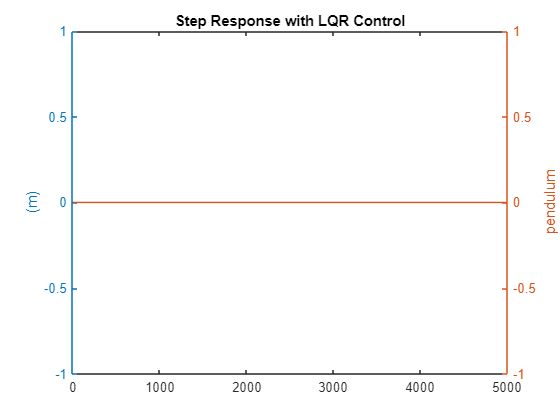

figure('Name', 'Output along state feedback');
[AX, H1, H2] = plotyy(t, y(:,1), t, y(:,2), 'plot');
set(get(AX(1), 'Ylabel'), 'String' , '(m)');
set(get(AX(2), 'Ylabel'), 'String' , 'pendulum');
title('Step Response with LQR Control');

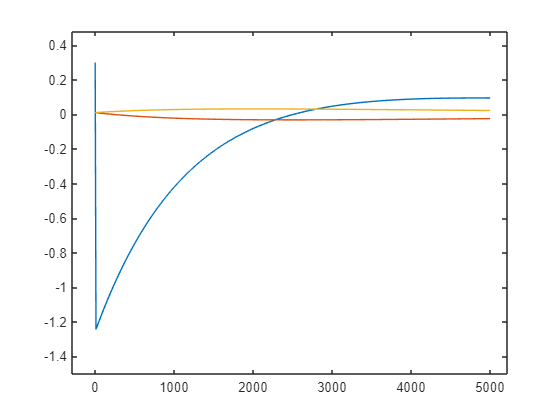

figure('Name', 'States along state feedback');
plot(t, x);


% синее это позиция героскопа
% оранжквое это угол
% красное это скорости

Запустим процесс

Вычисляем переходные процессы системы

display("Вычисляем переходные процессы системы")

    "Вычисляем переходные процессы системы"



%[y,t, x] = lsim(sys_cl,r,t,initCond)

Ak = A-B*K

Ak =   -10.0558 -618.6382 -644.2602
    0.0000         0         0
         0    0.0015    0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
   -1.2439    0.0095    0.0103
   -1.2315    0.0090    0.0106
   -1.2192    0.0085    0.0109
   -1.2070    0.0080    0.0112
   -1.1949    0.0075    0.0115
   -1.1829    0.0070    0.0117
   -1.1711    0.0065    0.0120
   -1.1593    0.0060    0.0123
   -1.1476    0.0056    0.0126


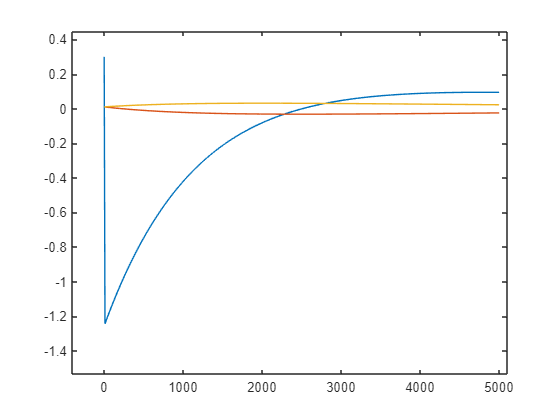

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off


% синее это позиция героскопа
% оранжквое это угол
% красное это скорости

# Эксперименты

display('Эксперименты')

Эксперименты


## До наблюдателя

Q = [100 0 0;
    0 100 0;
    0 0 100]

Q =    100     0     0
     0   100     0
     0     0   100


R = 30;
K = lqr(A,B,Q,R)

K =     6.1260  266.0427  310.6178


Попробуем

Ak = A-B*K

Ak =    -0.0039   -0.2077   -0.2220
    0.0000         0         0
         0    0.0015    0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.2459    0.0101    0.0103
    0.1930    0.0102    0.0106
    0.1412    0.0103    0.0109
    0.0907    0.0103    0.0112
    0.0413    0.0103    0.0116
   -0.0069    0.0104    0.0119
   -0.0540    0.0103    0.0122
   -0.1000    0.0103    0.0126
   -0.1449    0.0103    0.0129


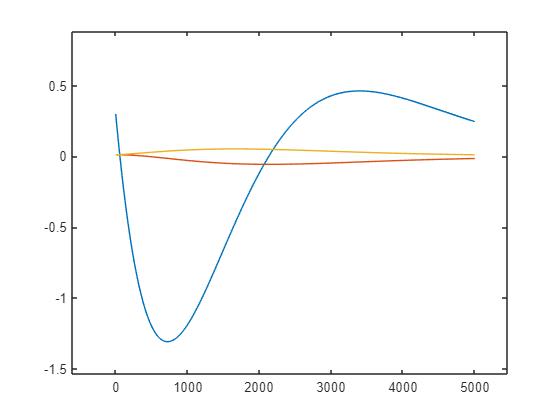

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Попробуем ускорить процесс и добавить больший штраф за управление, положив R = 10:

R = 10

R = 10

K = lqr(A,B,Q,R)

K =     7.5220  362.3985  407.2698


Ak = A-B*K

Ak =    -0.0048   -0.2694   -0.2839
    0.0000         0         0
         0    0.0015    0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.2313    0.0101    0.0103
    0.1647    0.0102    0.0106
    0.1003    0.0102    0.0109
    0.0378    0.0103    0.0112
   -0.0226    0.0103    0.0116
   -0.0811    0.0103    0.0119
   -0.1376    0.0102    0.0122
   -0.1923    0.0101    0.0126
   -0.2452    0.0101    0.0129


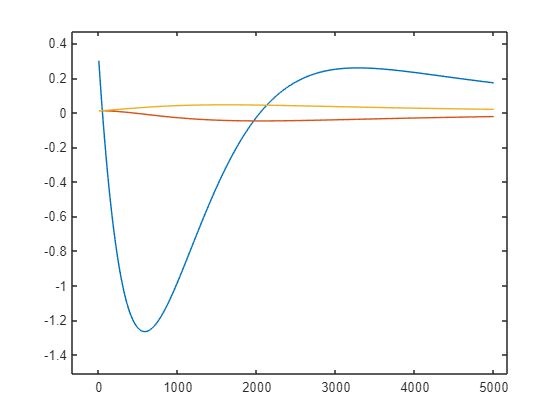

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Кажется в этом случае система стремится наоборот держать управление около 0. Поробуем увеличить штраф за отклонение положив Q = 1000*I

Q = 1000*eye(3);
R = 1;
K = lqr(A,B,Q,R)

K = 	1.0e+03 *

    0.0363    2.4709    2.5430


Ak = A-B*K

Ak =    -0.0232   -1.6190   -1.6510
    0.0000         0         0
         0    0.0015    0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
   -0.0568    0.0100    0.0103
   -0.3438    0.0100    0.0106
   -0.5738    0.0098    0.0109
   -0.7573    0.0095    0.0112
   -0.9028    0.0092    0.0115
   -1.0174    0.0088    0.0119
   -1.1067    0.0083    0.0122
   -1.1754    0.0079    0.0125
   -1.2274    0.0074    0.0128


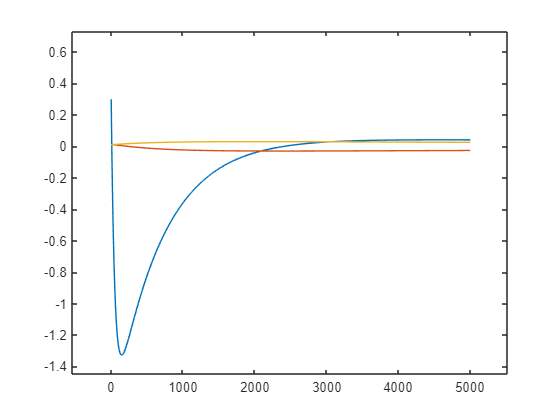

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Наибольшее отклонение от целевого значния дает именно первая переменная. Попробуем увеличить штраф за отклонение у нее, оставив штрафы у остальных переменных равными единице

Q = [100 0 0;
    0 1 0;
    0 0 1];
R = 1;
K = lqr(A,B,Q,R)

K =    14.5149  861.1172  905.5878


Ak = A-B*K

Ak =    -0.0093   -0.5886   -0.6029
    0.0000         0         0
         0    0.0015    0.0015


sys = ss(Ak, B, C, D, 'inputname', inputs, 'outputname', outputs);
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.1584    0.0101    0.0103
    0.0273    0.0101    0.0106
   -0.0941    0.0101    0.0109
   -0.2063    0.0101    0.0112
   -0.3099    0.0099    0.0116
   -0.4054    0.0098    0.0119
   -0.4934    0.0096    0.0122
   -0.5744    0.0094    0.0125
   -0.6487    0.0091    0.0129


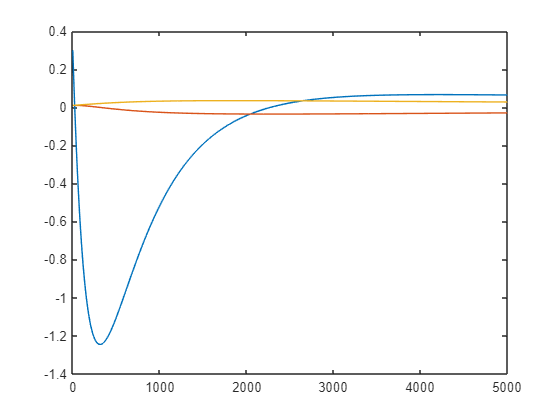

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

**УДАЛОСЬ стабилизировать**

Видно, что это привело к гораздо более быстрой сходимости. Посмотрим на большем временном интервале:

t = 0:10:5000; %в оригинальном тексте приводится решение для t_max < 2040
r = zeros(size(t)); %возмущения
[y,t,x] = lsim(sys, r, t, X0);
x

x =     0.3000    0.0100    0.0100
    0.1584    0.0101    0.0103
    0.0273    0.0101    0.0106
   -0.0941    0.0101    0.0109
   -0.2063    0.0101    0.0112
   -0.3099    0.0099    0.0116
   -0.4054    0.0098    0.0119
   -0.4934    0.0096    0.0122
   -0.5744    0.0094    0.0125
   -0.6487    0.0091    0.0129


plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

Видно, что затухание колебаний замедляется со временем, и уже после 2-3 тыс. с становится почти незаметной.

# Строим управление по наблюдению

display('матрица наблюдаемости для системы:')

матрица наблюдаемости для системы:


sys_ss

sys_ss =
 
  A = 
              x1         x2         x3
   x1          0   -0.03742    -0.0232
   x2  4.114e-05          0          0
   x3          0     0.0015     0.0015
 
  B = 
               u
   x1  0.0006401
   x2          0
   x3          0
 
  C = 
        x1  x2  x3
   x     0   0   0
   phy   0   0   0
 
  D = 
        u
   x    0
   phy  0
 
Continuous-time state-space model.



ob = obsv(sys_ss);
observability = rank(ob)

observability = 0

if observability ~=3
    display('наблюдаемая система')
else display('не наблюдаемая система')
end

наблюдаемая система



display('для оценки быстродействия замкнутой системы, находим собств значения')

для оценки быстродействия замкнутой системы, находим собств значения


poles = eig(Ac)

poles =   -10.0532
   -0.0008
   -0.0002


Теперь зададим желаемые значения и будем вводить уравнение расширенной замкнутой системы ( то етсь использование оценки Х)

Зададим вектор выхода системы произвольным образом:

C = [1 0.5 0.3;
    0.7 2 0.4;
    0 1 1];
D = [0;0;0] % выход не попадает в компоненты управления

D =      0
     0
     0


H = [C.'; A.'*C.'; (A.')^2*C.']; %observe
if rank(G) ~= 3
    display('Система ненаблюдаема');
else
    display('Ситема наблюдаема');
end

Ситема наблюдаема


Теперь сконструируем полного наблюдателя, для этого необходимо найти матрицу L. Матрицу L выберем исходя из формального равила, что собственные числа A-LC должны быть на порядок больше с.з. A-BK - то есть иметь свои значения в правой части

%Используем K с предыдущего шага
eigen_values = eig(Ak)

eigen_values =    -0.0061
   -0.0016
   -0.0001


L = place(A.', C.', 10*eigen_values).' % возращает матрицу коэф усиления

L =     0.0741   -0.0182   -0.0382
   -0.0074    0.0107   -0.0020
    0.0004   -0.0006    0.0025


Aobs = [A-B*K B*K;
    zeros(size(A)) A-L*C]

Aobs =    -0.0093   -0.5886   -0.6029    0.0093    0.5512    0.5797
    0.0000         0         0         0         0         0
         0    0.0015    0.0015         0         0         0
         0         0         0   -0.0614   -0.0000    0.0000
         0         0         0    0.0000   -0.0156   -0.0000
         0         0         0   -0.0000    0.0000   -0.0009


Bobs = [B; zeros(size(B))]

Bobs = 	1.0e+-3 *

    0.6401
         0
         0
         0
         0
         0


Cobs = [C zeros(size(C))]

Cobs =     1.0000    0.5000    0.3000         0         0         0
    0.7000    2.0000    0.4000         0         0         0
         0    1.0000    1.0000         0         0         0


Dobs = [0;0;0]

Dobs =      0
     0
     0


sys_obs = ss(Aobs, Bobs, Cobs, Dobs); % не включила ошибки
t = 0:10:2000; %в оригинальном тексте приводится решение для t_max < 2040
r = zeros(size(t)); %возмущения
X0obs = [X0; C*X0];
[y,t,x] = lsim(sys_obs, r, t, X0obs);
x

x =     0.3000    0.0100    0.0100    0.3080    0.2340    0.0200
    1.4276    0.0104    0.0103    0.1667    0.2002    0.0198
    2.2753    0.0111    0.0106    0.0902    0.1713    0.0196
    2.8940    0.0122    0.0110    0.0488    0.1466    0.0195
    3.3250    0.0135    0.0113    0.0264    0.1255    0.0193
    3.6026    0.0149    0.0117    0.0143    0.1073    0.0191
    3.7550    0.0164    0.0121    0.0077    0.0919    0.0189
    3.8059    0.0180    0.0126    0.0042    0.0786    0.0188
    3.7751    0.0196    0.0130    0.0023    0.0673    0.0186
    3.6793    0.0211    0.0135    0.0012    0.0576    0.0184


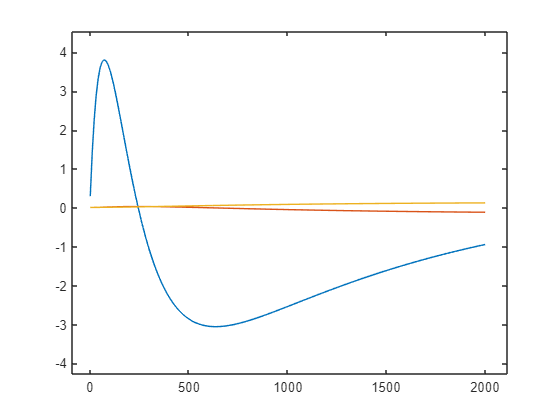

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off


% синее это позиция героскопа
% оранжквое это угол
% красное это скорости

Проверим другие условия

Q = [100 0 0;
    0 100 0;
    0 0 100];
R = 1;
K = lqr(A,B,Q,R);
Ak = A-B*K;
eigen_values = eig(Ak);
L = place(A.', C.', 10*eigen_values).';
Aobs = [A-B*K B*K;
    zeros(size(A)) A-L*C];
sys_obs = ss(Aobs, Bobs, Cobs, Dobs);
[y,t,x] = lsim(sys_obs, r, t, X0obs);
x

x =     0.3000    0.0100    0.0100    0.3080    0.2340    0.0200
    1.4352    0.0104    0.0103    0.1667    0.2002    0.0198
    2.2884    0.0111    0.0106    0.0902    0.1714    0.0196
    2.9108    0.0122    0.0110    0.0488    0.1466    0.0194
    3.3440    0.0135    0.0113    0.0264    0.1255    0.0191
    3.6226    0.0149    0.0117    0.0143    0.1074    0.0189
    3.7749    0.0165    0.0121    0.0077    0.0919    0.0187
    3.8250    0.0180    0.0126    0.0042    0.0786    0.0185
    3.7928    0.0196    0.0130    0.0023    0.0673    0.0183
    3.6949    0.0212    0.0135    0.0012    0.0576    0.0181


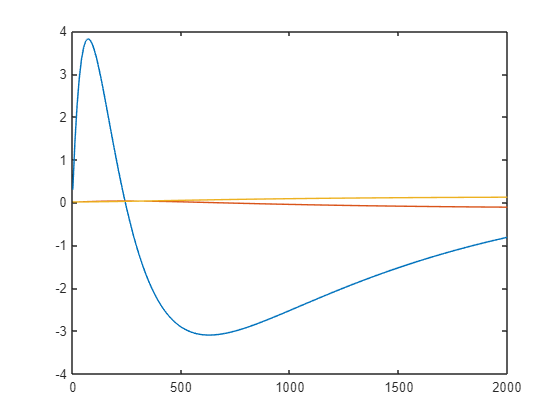

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off

и ещё

Q = 1000*eye(3);
R = 1;
K = lqr(A,B,Q,R);
Ak = A-B*K;
eigen_values = eig(Ak);
L = place(A.', C.', 10*eigen_values).';
Aobs = [A-B*K B*K;
    zeros(size(A)) A-L*C];
sys_obs = ss(Aobs, Bobs, Cobs, Dobs);
[y,t,x] = lsim(sys_obs, r, t, X0obs);
x

x =     0.3000    0.0100    0.0100    0.3080    0.2340    0.0200
    3.3124    0.0108    0.0103    0.0410    0.2013    0.0199
    5.2242    0.0126    0.0106    0.0055    0.1732    0.0197
    6.3314    0.0150    0.0110    0.0007    0.1490    0.0196
    6.8475    0.0177    0.0114    0.0001    0.1282    0.0195
    6.9358    0.0206    0.0119    0.0000    0.1103    0.0194
    6.7218    0.0234    0.0124    0.0000    0.0949    0.0192
    6.3013    0.0261    0.0130    0.0000    0.0816    0.0191
    5.7471    0.0285    0.0136    0.0000    0.0702    0.0190
    5.1138    0.0308    0.0142    0.0000    0.0604    0.0189


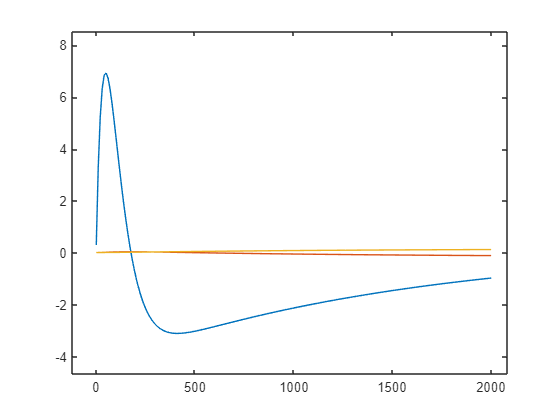

plot(t, x(:,1))
hold on
plot(t, x(:,2))
plot(t, x(:,3))
hold off